% Load toy dataset
load toy.dat
X = [ones(10, 1), toy(:, 1:2)] % first two cols of toy.dat

X =     1.0000    2.0000    3.0000
    1.0000    3.0000    2.0000
    1.0000    3.0000    6.0000
    1.0000    5.5000    4.5000
    1.0000    5.0000    3.0000
    1.0000    7.0000    4.0000
    1.0000    5.0000    6.0000
    1.0000    8.0000    6.0000
    1.0000    9.5000    5.0000
    1.0000    9.0000    7.0000


t = toy(:, 3) % just keep third column

t =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


[N, I] = size(X)

N = 10

I = 3

toy

toy =     2.0000    3.0000         0
    3.0000    2.0000         0
    3.0000    6.0000         0
    5.5000    4.5000         0
    5.0000    3.0000         0
    7.0000    4.0000    1.0000
    5.0000    6.0000    1.0000
    8.0000    6.0000    1.0000
    9.5000    5.0000    1.0000
    9.0000    7.0000    1.0000


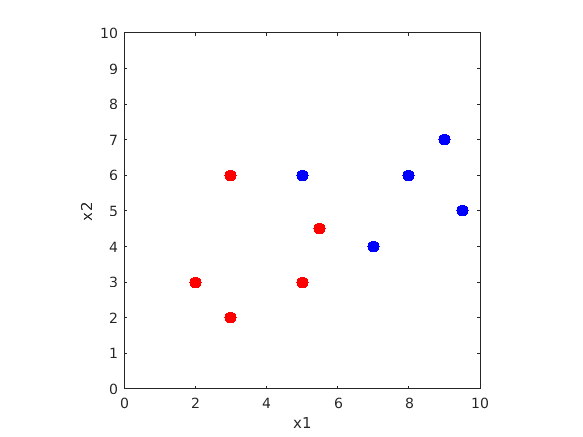

% Plot the data
figure(1); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); 
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30);
xlim([0 10])
ylim([0, 10]); 
axis square
xlabel('x1');
ylabel('x2');

rng('default');
ws = gradDescentSingleNeuron(X, t, 0.01)

ws =   -30.7143
    3.0039
    2.9251


wb =   -10.6762
    1.2284
    0.8417


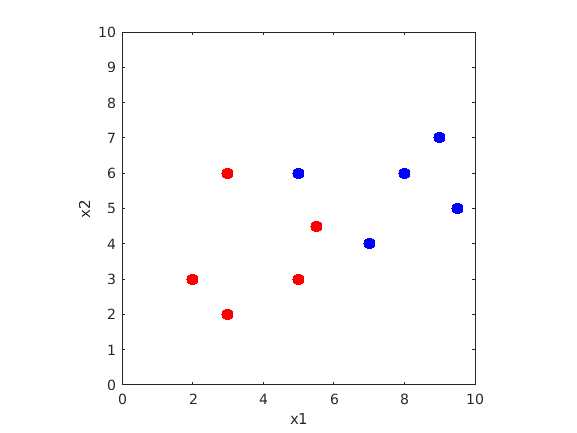

rng('default');
wb = gradDescentBayesSingleNeuron(X, t, 0.01, 0.01)

% Calculate learned Ys

learnedY = @(X) sigmoid(X * wb)

learnedY = function_handle with value:
    @(X)sigmoid(X*wb)


x1 = linspace(0, N)

x1 =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


x2 = x1; 
[x1 x2] = meshgrid(x1, x2) % places them as two blocks columnwise

x1 =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495
         0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    

x2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    0.1010    

% x2 seems to be a transpose of x1
% Put ones on first column, x1 values on second col
% and x2 values on third column
% Gives 1000 x 3 matrix
xs = [ones(10000, 1),  x1(:), x2(:)] 

xs =     1.0000         0         0
    1.0000         0    0.1010
    1.0000         0    0.2020
    1.0000         0    0.3030
    1.0000         0    0.4040
    1.0000         0    0.5051
    1.0000         0    0.6061
    1.0000         0    0.7071
    1.0000         0    0.8081
    1.0000         0    0.9091



% Then reshape the 1000 x 3 matrix to be 100 x 100
% while applying the learned function
learnedY_values = learnedY(xs)

learnedY_values =     0.2309
    0.2513
    0.2737
    0.2979
    0.3244
    0.3532
    0.3845
    0.4186
    0.4557
    0.4962


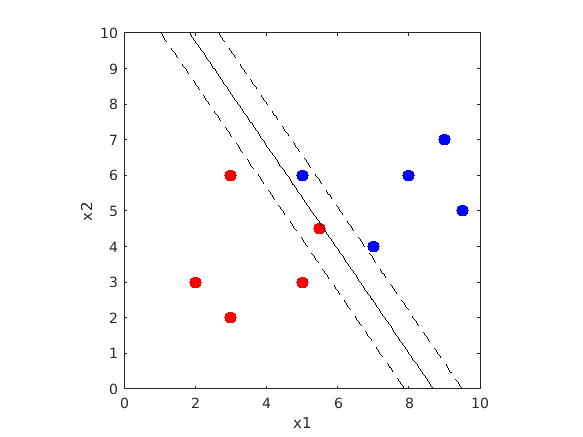

learnedY_values =     0.2309
    0.2513
    0.2737
    0.2979
    0.3244
    0.3532
    0.3845
    0.4186
    0.4557
    0.4962




% Plotting
figure(1); hold on

contour(x1, x2, reshape(learnedY_values, 100, 100), [0.27, 0.73], '--k'); 
hold on
contour(x1, x2, reshape(learnedY_values, 100, 100), [0.5, 0.5], 'k')